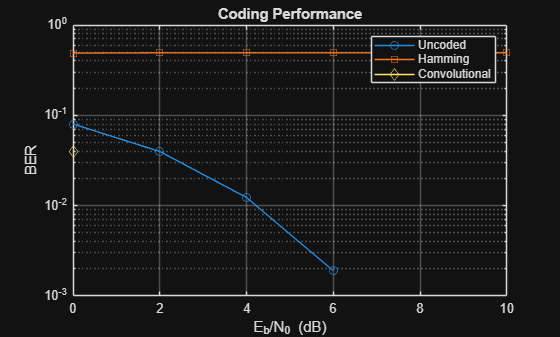

clc;
clear;
close all;

%% PARAMETERS
N = 1e4;
EbN0_dB = 0:2:10;

BER_uncoded = zeros(size(EbN0_dB));
BER_block = zeros(size(EbN0_dB));
BER_conv = zeros(size(EbN0_dB));

bits = randi([0 1], 1, N);

%% HAMMING (7,4)
G = [1 0 0 0 1 1 0;
     0 1 0 0 1 0 1;
     0 0 1 0 0 1 1;
     0 0 0 1 1 1 1];

%% CONVOLUTIONAL
trellis = poly2trellis(7, [171 133]);
tbl = 34;

%% LOOP
for k = 1:length(EbN0_dB)

    EbN0 = 10^(EbN0_dB(k)/10);
    noise_var = 1/(2*EbN0);

    %% ------------------ UNCODED
    s = 2*bits - 1;
    r = s + sqrt(noise_var)*randn(size(s));
    detected = r > 0;

    BER_uncoded(k) = sum(bits ~= detected)/length(bits);

    %% ------------------ HAMMING
    msg_len = floor(length(bits)/4)*4;
    msg = reshape(bits(1:msg_len), 4, []).';

    code = mod(msg * G, 2);
    code = code(:).';

    s = 2*code - 1;
    r = s + sqrt(noise_var)*randn(size(s));
    detected = r > 0;

    detected = reshape(detected, 7, []).';
    decoded = detected(:,1:4);
    decoded = decoded(:).';

    orig = msg(:).';

    min_len = min(length(orig), length(decoded));
    BER_block(k) = sum(orig(1:min_len) ~= decoded(1:min_len))/min_len;

    %% ------------------ CONVOLUTIONAL
    encoded = convenc(bits, trellis);

    s = 2*encoded - 1;
    r = s + sqrt(noise_var)*randn(size(s));

    decoded = vitdec(r > 0, trellis, tbl, 'trunc', 'hard');

    min_len = min(length(bits), length(decoded));
    BER_conv(k) = sum(bits(1:min_len) ~= decoded(1:min_len))/min_len;

end

%% PLOT
figure;
semilogy(EbN0_dB, BER_uncoded, 'o-', ...
         EbN0_dB, BER_block, 's-', ...
         EbN0_dB, BER_conv, 'd-');

legend('Uncoded','Hamming','Convolutional');
xlabel('E_b/N_0 (dB)');
ylabel('BER');
title('Coding Performance');
grid on;